# Implementing ROC curves

You're working for a web applications company who use machine learning in many of their projects and have in-house implementations of a number of different classifiers and evaluation methods. At the moment all staff are using confusion matrices when training their classifiers and tuning hyperparameters. Your boss has asked you to implement a new Receiver Operating Characteristic (ROC) curve function which will use both the predicted class labels and likelihood scores from any given classifier in order to generate an ROC curve. 

As a first step, you've agreed to implement your basic approach in Matlab and check you can exactly recreate results from Matlab's built-in `perfcurve()` function. (You can then port your solution over to another language once you're certain your approach is sound.) Your boss has provided you with some pre-trained classifiers and data with which you can test the behaviour of the built-in `perfcurve()` function:

clear all;

% load some 2 classifiers and some data to help us:
load('classifiers.mat', 'm_knn', 'm_nb', 'test_examples', 'test_labels');

% add as many lines of code as you need below:
[predictions, scores] = m_nb.predict(test_examples)

predictions = 142×1 categorical array
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 


scores =     0.0000    1.0000
    0.0000    1.0000
    1.0000    0.0000
    1.0000    0.0000
    0.0000    1.0000
    0.0000    1.0000
    1.0000    0.0000
    1.0000    0.0000
    0.0000    1.0000
    1.0000    0.0000


m_nb.ClassNames %find order of class names so Malignant can be taken as positive class

ans = 2×1 categorical array
     Benign 
     Malignant 


[x,y,~,AUC] = perfcurve(test_labels, scores(:, 2), m_nb.ClassNames(2));
AUC %area under curve

AUC = 0.9769

plot(x,y)
hold("on")

[predictions, scores] = m_knn.predict(test_examples)

predictions = 142×1 categorical array
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 


scores =      0     1
     0     1
     1     0
     1     0
     0     1
     0     1
     1     0
     1     0
     0     1
     1     0


m_knn.ClassNames %find order of class names so Malignant can be taken as positive class

ans = 2×1 categorical array
     Benign 
     Malignant 


[x,y,~,AUC] = perfcurve(test_labels, scores(:, 2), m_knn.ClassNames(2));
AUC %area under curve

AUC = 0.9854

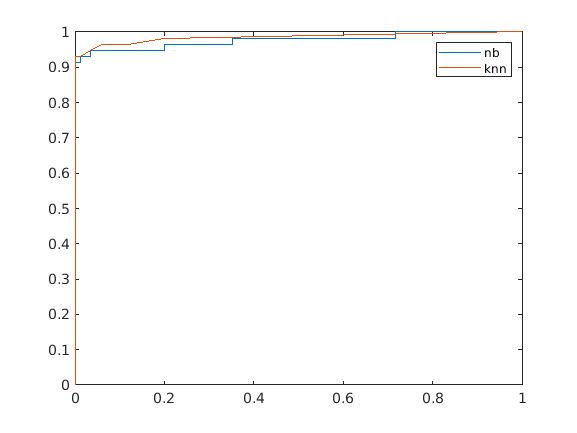

plot(x,y)
legend("nb", "knn")

hold("off")

[fprs, tprs] = my_roc(test_labels, scores(:, 2), m_knn.ClassNames(2))

thresholds =     1.0000
    0.9000
    0.8000
    0.7000
    0.6000
    0.4000
    0.3000
    0.2000
    0.1000
         0


fprs =          0         0         0         0         0    0.0118    0.0353    0.0588    0.1176    0.2000    1.0000


tprs =          0    0.7018    0.8246    0.8772    0.9298    0.9298    0.9474    0.9649    0.9649    0.9825    1.0000


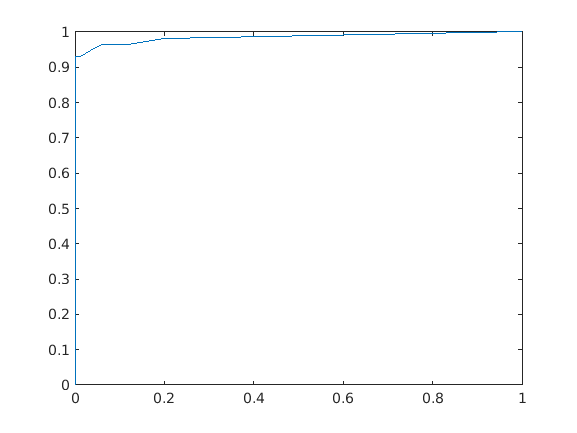

plot(fprs,tprs)

Your boss has also provided you with some skeleton code for a `my_roc()` function (below) which roughly sketches what they expect your solution to look like. Your task is to get this function working correctly. Marks are available for:

- **In the code listing above**: Using `perfcurve()` to generate an ROC curve for each classifier, taking "Malignant" as the positive class, and plotting them together on a single graph with a legend and labelled axes [4 marks]

- **In the **`my_roc()`** function below**: Deciding the likelihood thresholds over which the outer for loop in `my_roc()` should iterate [4 marks]

- **In the **`my_roc()`** function below**: Updating the `tn`, `fp`, `fn` and `tp` count variables as appropriate inside the inner loop [4 marks]

- **In the **`my_roc()`** function below**: Calculating the resulting True Positive Rate and False Positive Rate and storing both results [4 marks]

- **In the code listing above**: Convincing yourself that `my_roc()` is working as it should by plotting a new figure to compare with the one you generated in part 1 [4 marks]

[20 marks]

function [fprs, tprs] = my_roc(labels, scores, posclass)
    
    % start off arrays to hold the True Positive and False Positive Rates:
    tprs = 0;
    fprs = 0;

    % determine the name of the non-positive class:
    all_labels = unique(labels);
    other = setdiff(all_labels, posclass);
    
    thresholds = [];
    % Decide the likelihood thresholds over which we should loop:
    
    
    
    % for every threshold value:
    for i = 1:1:length(thresholds)
        
        % set the new threshold:
        threshold = thresholds(i);
        
        % initialise count variables for:
        tn = 0; % True Negatives
        fp = 0; % False Positives
        fn = 0; % False Negatives
        tp = 0; % True Positives
        
        % for every classification:
        for j = 1:length(scores)
            
            % is the associated classification score greater than the current threshold
            if scores(j) >= threshold
                % was the example truly a member of the positive class?
                if labels(j) == posclass
                    % update the appropriate count variable:
                    %...
                    tp = tp + 1;
                else
                    
                    % update the appropriate count variable:
                    %...
                    fp = fp + 1;
                end 
            else
                % was the example truly a member of the other class?
                if labels(j) == other
                    % update the appropriate count variable:
                    %...
                    tn = tn + 1;
                else
                    % update the appropriate count variable:
                    %...
                    fn = fn + 1;
                end
            end
            
        end
        
        % calculate the updated True Positive and False Positive Rates and
        % store them:
        tprs(end+1) = tp/(tp + fn);
        fprs(end+1) = fp/(fp + tn);
        
    end
    
end